syms t
f_hat = [1, t, t^2, t^3, t^4]

$$f\_hat = \left(\begin{array}{ccccc} 1 & t & t^{2} & t^{3} & t^{4} \end{array}\right)$$

G = sym('G', [5 5]);
for i = 1:5
    for j = 1:5
        G(i,j) = int(f_hat(i)*f_hat(j), 0, pi);
    end
end
G

$$G = \left(\begin{array}{ccccc} \pi & \frac{\pi^{2}}{2} & \frac{\pi^{3}}{3} & \frac{\pi^{4}}{4} & \frac{\pi^{5}}{5}\\ \frac{\pi^{2}}{2} & \frac{\pi^{3}}{3} & \frac{\pi^{4}}{4} & \frac{\pi^{5}}{5} & \frac{\pi^{6}}{6}\\ \frac{\pi^{3}}{3} & \frac{\pi^{4}}{4} & \frac{\pi^{5}}{5} & \frac{\pi^{6}}{6} & \frac{\pi^{7}}{7}\\ \frac{\pi^{4}}{4} & \frac{\pi^{5}}{5} & \frac{\pi^{6}}{6} & \frac{\pi^{7}}{7} & \frac{\pi^{8}}{8}\\ \frac{\pi^{5}}{5} & \frac{\pi^{6}}{6} & \frac{\pi^{7}}{7} & \frac{\pi^{8}}{8} & \frac{\pi^{9}}{9} \end{array}\right)$$


f = sin(t);
y = int(f*f_hat, 0, pi)

$$y = \left(\begin{array}{ccccc} 2 & \pi & \pi^{2}-4 & \pi^{3}-6\,\pi & \pi^{4}-12\,\pi^{2}+48 \end{array}\right)$$


G = eval(G);
y = eval(y);
alpha = y*inv(G)

alpha =     0.0013    0.9826    0.0545   -0.2338    0.0372


d = sqrt(eval(int(f*f, 0, pi)) - y*inv(G)*y')

d = 6.5408e-04


x = linspace(0,pi);

x =          0    0.0317    0.0635    0.0952    0.1269    0.1587    0.1904    0.2221    0.2539    0.2856    0.3173    0.3491    0.3808    0.4125    0.4443    0.4760    0.5077    0.5395    0.5712    0.6029    0.6347    0.6664    0.6981    0.7299    0.7616    0.7933    0.8251    0.8568    0.8885    0.9203    0.9520    0.9837    1.0155    1.0472    1.0789    1.1107    1.1424    1.1741    1.2059    1.2376    1.2693    1.3011    1.3328    1.3645    1.3963    1.4280    1.4597    1.4915    1.5232    1.5549


f = eval(subs(f, x));

f =          0    0.0317    0.0634    0.0951    0.1266    0.1580    0.1893    0.2203    0.2511    0.2817    0.3120    0.3420    0.3717    0.4009    0.4298    0.4582    0.4862    0.5137    0.5406    0.5671    0.5929    0.6182    0.6428    0.6668    0.6901    0.7127    0.7346    0.7557    0.7761    0.7958    0.8146    0.8326    0.8497    0.8660    0.8815    0.8960    0.9096    0.9224    0.9341    0.9450    0.9549    0.9638    0.9718    0.9788    0.9848    0.9898    0.9938    0.9969    0.9989    0.9999


fh = eval(subs(f_hat*alpha', x));

fh =     0.0013    0.0325    0.0638    0.0952    0.1264    0.1577    0.1888    0.2198    0.2506    0.2812    0.3115    0.3416    0.3713    0.4006    0.4295    0.4581    0.4861    0.5137    0.5407    0.5672    0.5931    0.6185    0.6431    0.6672    0.6905    0.7131    0.7350    0.7562    0.7766    0.7962    0.8150    0.8329    0.8500    0.8663    0.8817    0.8962    0.9097    0.9224    0.9341    0.9449    0.9548    0.9637    0.9716    0.9785    0.9845    0.9895    0.9935    0.9965    0.9985    0.9995


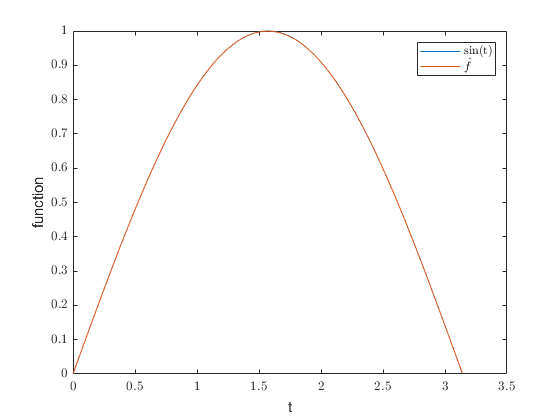


figure
plot(x, f)
hold on
plot(x, fh)
xlabel('t')
ylabel('function')
legend('sin(t)', '$\hat{f}$')

syms t
f_hat = [exp(-t), exp(-2*t)]

$$f\_hat = \left(\begin{array}{cc} {\mathrm{e}}^{-t} & {\mathrm{e}}^{-2\,t} \end{array}\right)$$

G = sym('G', [2,2]);
for i = 1:2
    for j = 1:2
        G(i,j) = int(f_hat(i)*f_hat(j), 0, inf);
    end
end
G

$$G = \left(\begin{array}{cc} \frac{1}{2} & \frac{1}{3}\\ \frac{1}{3} & \frac{1}{4} \end{array}\right)$$


f = exp(-3*t);
y = int(f*f_hat, 0, inf)

$$y = \left(\begin{array}{cc} \frac{1}{4} & \frac{1}{5} \end{array}\right)$$


G = eval(G);
y = eval(y);
alpha = y*inv(G)

alpha =    -0.3000    1.2000


d = sqrt(eval(int(f*f, 0, pi)) - y*inv(G)*y')

d = 0.0408

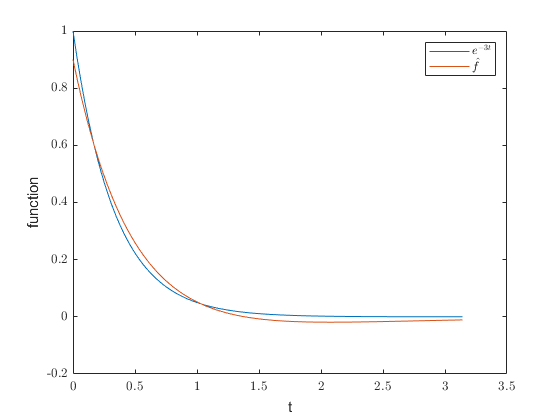


x = linspace(0,pi);
f = eval(subs(f, x));
fh = eval(subs(f_hat*alpha', x));

figure
plot(x, f)
hold on
plot(x, fh)
xlabel('t')
ylabel('function')
legend('$e^{-3t}$', '$\hat{f}$')

syms t
A = [-4, -6; 1 1]

A =     -4    -6
     1     1


C = [2 1]

C =      2     1


obsv(A,C)

ans =      2     1
    -7   -11


C*expm(A*t)

$$ans = \left(\begin{array}{cc} 5\,{\mathrm{e}}^{-2\,t}-3\,{\mathrm{e}}^{-t} & 10\,{\mathrm{e}}^{-2\,t}-9\,{\mathrm{e}}^{-t} \end{array}\right)$$

alpha = inv([-3 -9;5 10])*[-0.3;1.2]

alpha =     0.5200
   -0.1400



P = int(expm(A'*t)*C'*C*expm(A*t), 0, inf)

$$P = \left(\begin{array}{cc} \frac{3}{4} & 1\\ 1 & \frac{11}{2} \end{array}\right)$$

x0 = inv(P)*int(expm(A'*t)*C'*exp(-3*t), 0, inf)

$$x0 = \left(\begin{array}{c} \frac{13}{25}\\ -\frac{7}{50} \end{array}\right)$$

y = C*expm(A*t)*x0

$$y = \frac{6\,{\mathrm{e}}^{-2\,t}}{5}-\frac{3\,{\mathrm{e}}^{-t}}{10}$$

d = sqrt(int(exp(-3*t)^2, 0, inf)-x0'*P*x0)

$$d = \frac{\sqrt{6}}{60}$$

d = eval(d)

d = 0.0408


t = linspace(0, pi);
f = exp(-3*t)

f =     1.0000    0.9092    0.8266    0.7516    0.6833    0.6213    0.5648    0.5136    0.4669    0.4245    0.3860    0.3509    0.3191    0.2901    0.2637    0.2398    0.2180    0.1982    0.1802    0.1639    0.1490    0.1354    0.1231    0.1120    0.1018    0.0926    0.0841    0.0765    0.0696    0.0632    0.0575    0.0523    0.0475    0.0432    0.0393    0.0357    0.0325    0.0295    0.0268    0.0244    0.0222    0.0202    0.0183    0.0167    0.0152    0.0138    0.0125    0.0114    0.0104    0.0094


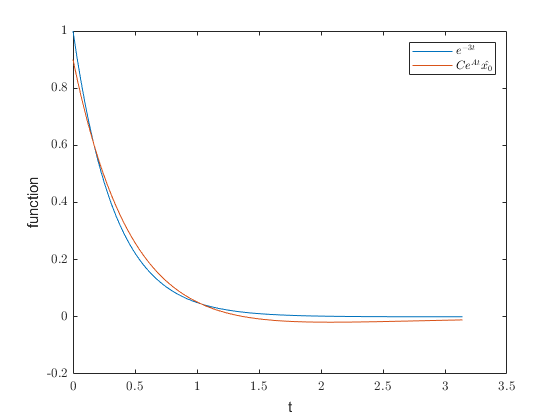

fh = 1.2*exp(-2*t)-0.3*exp(-t);
figure
plot(t,f)
hold on
plot(t,fh)
xlabel('t')
ylabel('function')
legend('$e^{-3t}$', '$Ce^{At}\hat{x_0}$')

T = [3 2;4 -2;3 2; -1 3]

T =      3     2
     4    -2
     3     2
    -1     3


y = [2 4 3 8]'

y =      2
     4
     3
     8


rank(T)

ans = 2

u = pinv(T)*y

u =     0.6226
    1.2084


d = sqrt(norm(y)^2-u'*(T'*T*u))

d = 6.8746

T = [1 2; 1 2; 2 4; 3 6]

T =      1     2
     1     2
     2     4
     3     6


T'*T

ans =     15    30
    30    60


T'*y

ans =     36
    72
